# Interpolare Spline (cubica de clasa C^2)

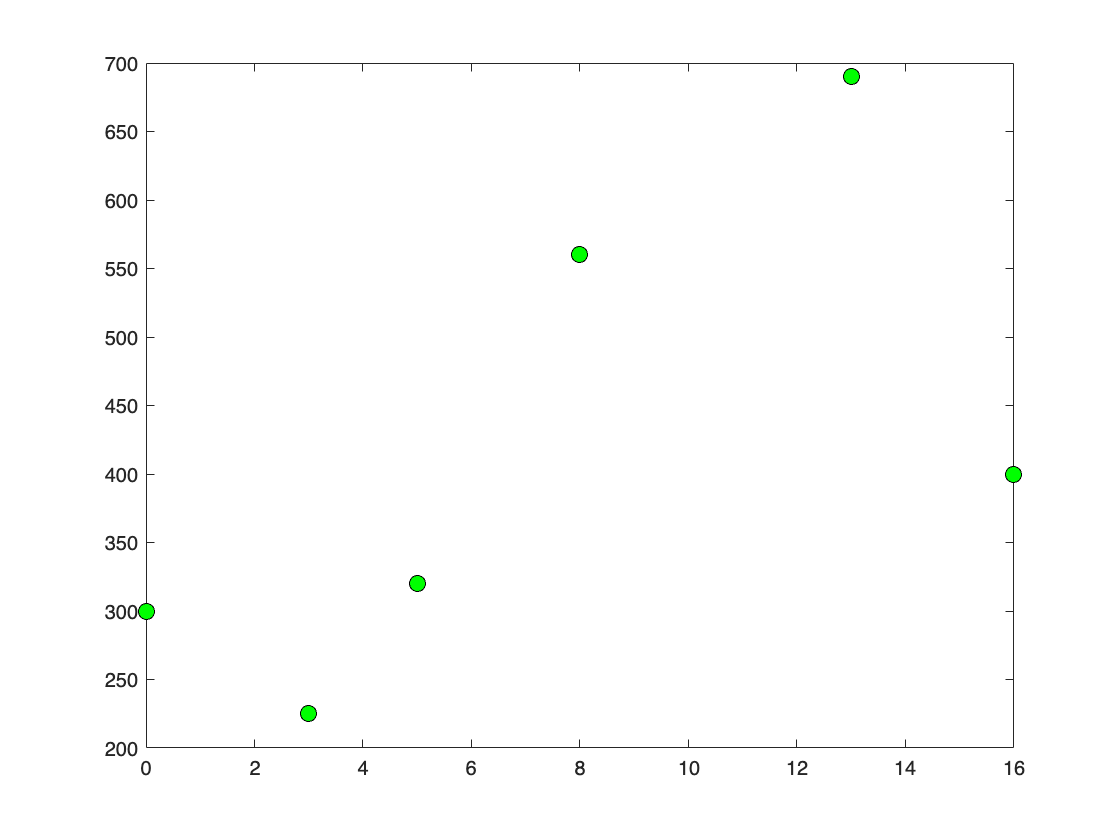

nodes=[0 3 5 8 13 16];
X=linspace(0,16,1000);
values=[300  225  320  560  690 400];
plot(nodes, values, 'ok', 'markerfacecolor', 'g', 'markersize', 8);

names={'nodes', 'complete' 'naturale' 'derivate2' 'deBoor'}

names = 1×5 cell array
    {'nodes'}    {'complete'}    {'naturale'}    {'derivate2'}    {'deBoor'}


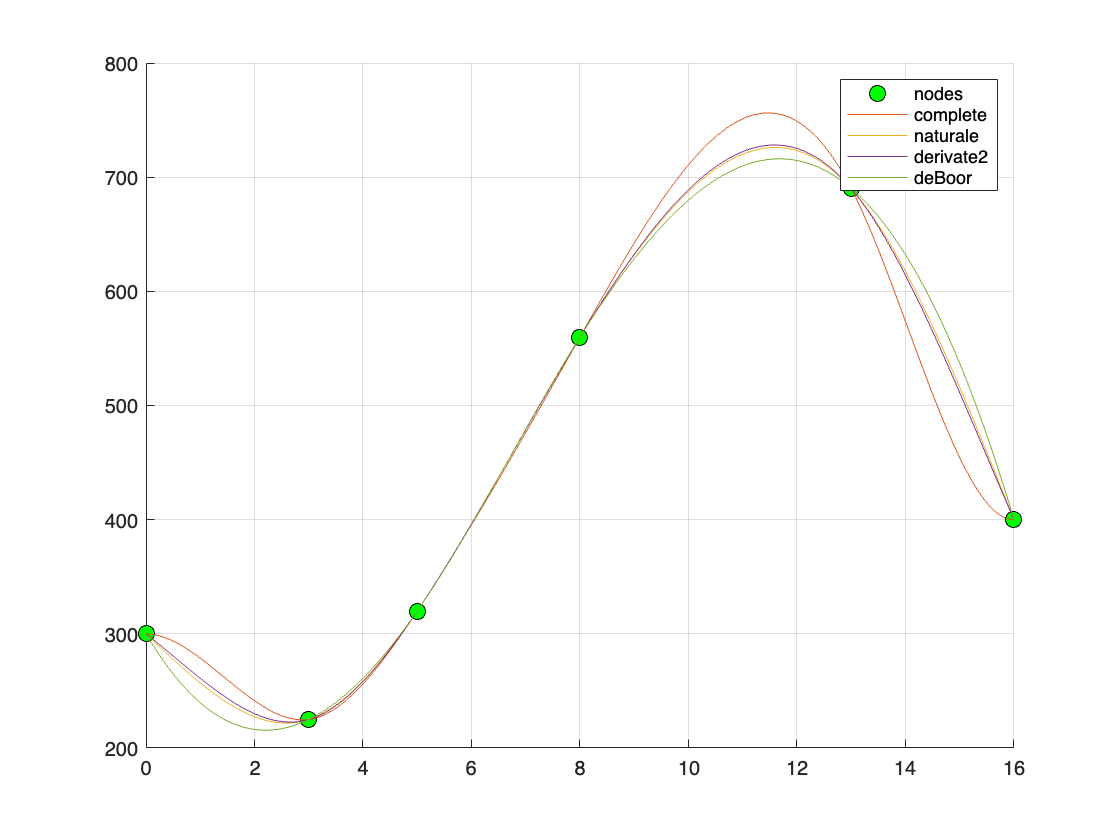

splineComplete=evalsplinecubic(nodes, values, names{2}, [-1 1], X);
splineNaturale=evalsplinecubic(nodes, values, names{3}, [], X);
splineDerivative2=evalsplinecubic(nodes, values, names{4}, [-10 10], X);
splineDeBoor=evalsplinecubic(nodes, values, names{5}, [], X);

clf; hold on; grid on;

plot(nodes, values, 'ok', 'markerfacecolor', 'g', 'markersize', 8);
plot(X, splineComplete);
plot(X, splineNaturale);
plot(X, splineDerivative2);
plot(X, splineDeBoor);
legend(names)